# **Lab 1: Introduction to** `MATLAB`

%-------------------------------------------------------------------------%
%*             ECSE 307 - Winter 2018 - Prof. Aditya Mahajan             *%
%*                TA: Mohammad Afshari and Anas El Fathi                 *%
%-------------------------------------------------------------------------%
%*                                                                       *%
%* Fill in your group number.                                            *%
GroupeNum = 19;
%* Fill in your student Name and ID.                                     *%
Students(1).Name = 'Nayem Alam';
Students(1).ID   = '260743549';
Students(2).Name = 'Yassine Douida';
Students(2).ID   = '260741964';
%-------------------------------------------------------------------------%

## **0. Objectives**

This first lab is divided into two parts. The first part is an introduction to some usefull functions in `MATLAB` and how they will be used in the series of following labs. The second part is an application of how to calculate Laplace and inverse Laplace using `MATLAB`.

## **1. Usefull functions**

## *1.1. Publishing a LiveScript in* `MATLAB`

A `MATLAB` LiveScript is an interactive document that combines `MATLAB` code with embedded output, formatted text, equations, and images in a single environment called the Live Editor. LiveScripts are stored using the LiveScript file format in a file with a .mlx extension.

A `MATLAB` LiveScript file will be provided in each lab. You should read and answer the questions inside the LiveScript document. At the end of the lab:

- Make sure that the LiveScript document runs without errors.

- Export the LiveScript to a PDF format (Click on the arrow under the save icon).

- Submit the LiveScript and the genrated PDF into the group submission in myCourses.

- If requested attach any autogenerated MAT-file (explained in section 1.4).

## *1.1. Arrays in* `MATLAB`

Matrices and arrays are the fundamental representation of information and data in `MATLAB`. For a beginner overview of matrix and array manipulation, watch the following video [Working with Arrays in MATLAB](https://www.mathworks.com/videos/working-with-arrays-in-matlab-101637.html).

To work with signals and systems we will usually define a discrete time signal as an array. An example of time signal is:

dt = 0.01; % timestep of discrete signal in seconds
T = 10; % Final value of the time signal in seconds
time = 0:dt:T; % time signal

A sine wave signal of amplitude 1 and period 1 rad/second


$$ u1 = sin(2 \pi t) $$


can be written as

u1 = sin(2*pi*time);

One can also use logical oprations to construct a desired signal. For example, the following signal


$$u_2(t) = \begin{cases}  t, & 0 \leq t < 5 \\ -t+10,  & t \geq 5\end{cases}$$


Can be written as

u2 = zeros(size(time)); % create a zero signal with the same size as time
u2(time < 5) = time(time < 5); % value is equale to time, but only when time < 5
u2(time >= 5) = -time(time >= 5) + 10; % value is equale to -time+10, but only when time >= 5

## *1.3. Plotting in* `MATLAB`

In order to present results you can use the `plot` function. `plot(X,Y)` creates a 2-D line plot of the data in Y versus the corresponding values in X.

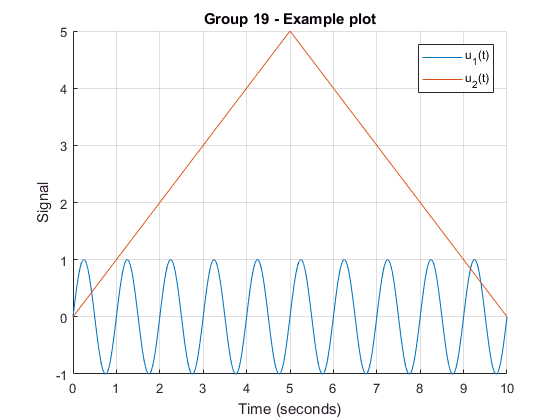

figure;
hold on;
plot(time, u1);
plot(time, u2);
title(sprintf('Group %d - Example plot', GroupeNum));
xlabel('Time (seconds)')
ylabel('Signal')
grid on;
legend('u_1(t)', 'u_2(t)')

## *1.4. Saving/loading in* `MATLAB`

In `MATLAB` you can save any or all the variables in the current workspace to a MAT-file (.mat). You can then reuse the workspace variables later during the current MATLAB session or during another session by loading the saved MAT-file.

Example:

example = 'Example for Saving/loading in MATLAB !';
save('Lab01_results.mat','example')

You can recover your workspace from the MAT-file, by doing

load('Lab01_results.mat','example')
disp(example)

Example for Saving/loading in MATLAB !


For hardware labs (labs that requires the use of external hardware) the result of your manipulation will be saved autmatically in this manner. The resulting file can be used to re-examine your data, or change your plots. In the end of the hardware lab, you will be requested to submit the MAT-file.

## *Question 1 (4 marks)*

Answer the following questions in the LiveScript.

- Define a time signal from 0 to 10 seconds, with a timestep of 0.1 second.

time = (0:0.1:10);

- Define a unit signal equals to 1 from 0 to 10 second.


$$v_1(t) = 1, t \geq 0$$


v1(time >= 0) = 1;

- Define a delayed signal equals zero from 0 to 5 seconds and to -1 from 5 to 10 seconds.


$$v_2(t) = \begin{cases}  0, & t < 5 \\  -1,  & t \geq 5\end{cases}$$


v2 = zeros(size(time));
v2(time < 5) = 0;
v2(time >= 5) = -1;

- Define a ramp signal with slope equals 0.1.


$$v_3(t) = 0.1 t, t \geq 0$$


v3 = 0.1*(time);

- Define a decaying exponential signal with time constant of 10 second.


$$v_4(t) = e^{-\frac{t}{10}}$$


v4 = exp(-time/10);

- Plot in the same graph the signals ($v_1(t)$, $v_2(t)$, $v_3(t)$, and $v_4(t)$) versus the time signal.

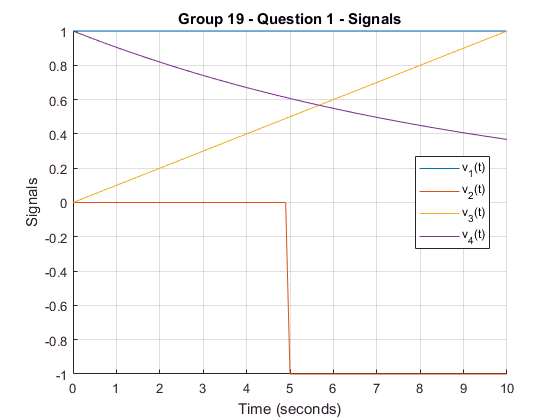

figure;
hold on
% fill in your plots command
plot(time,v1); 
plot(time,v2);
plot(time,v3);
plot(time,v4);
title(sprintf('Group %d - Question 1 - Signals', GroupeNum));
xlabel('Time (seconds)')
ylabel('Signals')
grid on;
legend('v_1(t)', 'v_2(t)', 'v_3(t)', 'v_4(t)', 'location', 'best')

## **2. Laplace transforms**

The laplace transform of a function $f(t)$ is defined as follows:


$$ F(s) = \int_{0^-}^{+\infty} f(t) e^{-s t} dt $$


## *2.1. Caluclating laplace transform with* `MATLAB`

The command `laplace` in `MATLAB` provides an easy way to calculate the Laplace transform $F(s)$ of a function $f(t)$. To use `laplace`, first you need to specify that the variable $t$ and $s$ are symbolic ones. This is done with the command

syms t s

Next you define the function $f(t)$. For instance, for $f(t) = e^{-t}$ you do

f = exp(-t)

$$f = {\mathrm{e}}^{-t}$$

The actual command to calculate the transform is

F = laplace(f,t,s)

$$F = \frac{1}{s+1}$$

For more information about `laplace` type

help laplace

--- help for sym/laplace ---

 laplace Laplace transform.
    L = laplace(F) is the Laplace transform of the sym F with default
    independent variable t.  The default return is a function of s.
    If F = F(s), then laplace returns a function of z:  L = L(z).
    By definition, L(s) = int(F(t)*exp(-s*t),t,0,inf).
 
    L = laplace(F,z) makes L a function of z instead of the default s:
    laplace(F,z) <=> L(z) = int(F(t)*exp(-z*t),t,0,inf).
 
    L = laplace(F,w,u) makes L a function of u instead of the
    default s (integration with respect to w).
    laplace(F,w,u) <=> L(u) = int(F(w)*exp(-u*w),w,0,inf).
 
    Examples:
     syms a s t w x F(t)
     laplace(t^5)          returns   120/s^6
     laplace(exp(a*s))     returns   -1/(a-z)
     laplace(sin(w*x),t)   returns   w/(t^2+w^2)
     laplace(cos(x*w),w,t) returns   t/(t^2+x^2)
     laplace(x^(3

## *Question 2 (2 marks)*

Write the symbolic expression of the following functions (you can use the symbolic varibales `t` and `s` defined previously):

- $f_1(t) = \delta(t)$ ($\delta(t)$ is the dirac function, use `help dirac` for more information)

- 
$$f_2(t) = t^2 + t + 1$$


- 
$$f_3(t) = te^{-t} + 0.5e^{-t} + e^{-5t}$$


- 
$$f_4(t) = \sin(2t) + \cos^2(t)$$


- 
$$f_5(t) = e^{-t}\sin(5 t + \frac{\pi}{3})+t^2 e^{-2t}$$


f1 = dirac(t);
f2 = t^2+t+1;
f3 = t*exp(-t)+ 0.5*exp(-t)+ exp(-5*t);
f4 = sin(2*t) + (cos(t)^2);
f5 = exp(-t)*sin(5*t+pi/3) + t^2*exp(-2*t);

## *2.2. Symbolic expression simplification*

To make the symbolic expression more readable one can use the function `simplify` (`help simplify` for more information) to performs algebraic simplification. For example

simplify(2/(s+1) - s/(s+1)^2)

$$ans = \frac{s+2}{{\left(s+1\right)}^{2}}$$

## *Question 3 (2 marks)*

Use `Matlab` functions calulate the Laplace transform of the functions defined in *Question 2*. Use `simplify` to simplify the symbolic expression if needed.

F1 = laplace(f1,t,s)

$$F1 = 1$$

F2 = simplify(laplace(f2,t,s))

$$F2 = \frac{s^{2}+s+2}{s^{3}}$$

F3 = simplify(laplace(f3,t,s))

$$F3 = \frac{3\,s^{2}+12\,s+17}{2\,{\left(s+1\right)}^{2}\,\left(s+5\right)}$$

F4 = simplify(laplace(f4,t,s))

$$F4 = \frac{s^{2}+2\,s+2}{s\,\left(s^{2}+4\right)}$$

F5 = simplify(laplace(f5,t,s))

$$F5 = \frac{2}{{\left(s+2\right)}^{3}}+\frac{5}{2\,\left({\left(s+1\right)}^{2}+25\right)}+\frac{\sqrt{3}\,\left(s+1\right)}{2\,\left({\left(s+1\right)}^{2}+25\right)}$$

## *2.3. Caluclating inverse laplace transform with* `MATLAB`

To calculate the inverse laplace transform you can use the command `ilaplace`. One also needs to define the symbols t and s.

Example

ilaplace(F, s, t);

## *Question 4 (2 marks)*

Use `Matlab` functions to calulate the inverse Laplace transform of the following expressions. Use `simplify` to simplify the symbolic expression if needed.

- 
$$G_1(s) = \frac{1}{s}$$


- 
$$G_2(s) = \frac{1}{s(s+1)}$$


- 
$$G_3(s) = \frac{3}{s^2+25}$$


- 
$$G_4(s) = \frac{10s+1}{s^2+2s+10}$$


- 
$$G_5(s) = \frac{2(s+1)(s^2+4)}{(s^2+4s+2)(s^2+9)}$$


g1 = simplify(ilaplace(1/s,s,t))

$$g1 = 1$$

g2 = simplify(ilaplace(1/(s*(s+1)),s,t))

$$g2 = 1-{\mathrm{e}}^{-t}$$

g3 = simplify(ilaplace(3/(s^2+25),s,t))

$$g3 = \frac{3\,\sin\left(5\,t\right)}{5}$$

g4 = simplify(ilaplace((10*s+1)/((s^2)+2*s+10), s, t))

$$g4 = 10\,{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)-\frac{3\,\sin\left(3\,t\right)}{10}\right)$$

g5 = simplify(ilaplace((2*(s+1)*((s^2)+4))/(((s^2)+4*s+2)*((s^2)+9)), s, t))

$$g5 = \frac{110\,\cos\left(3\,t\right)}{193}-\frac{290\,\sin\left(3\,t\right)}{579}+\frac{276\,{\mathrm{e}}^{-2\,t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\frac{79\,\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)}{138}\right)}{193}$$